# Integración en Varias Variables

Para funciones de varias variables, la integración se puede realizar mediante:

Integrales dobles sobre una superficie dada como

 
$$\int_a^b \int_{y_{min}(x)}^{y_{max}(x)} f(x,y) dx dy$$


Integrales triples sobre un volumen dada como


$$\int_a^b \int_{y_{min}(x)}^{y_{max}(x)} \int_{z_{min}(x,y)}^{z_{max}(x,y)} f(x,y,z) dx dy dz$$


En el caso de la formula de Simpson en tres dimensiones, la formula de Simpson tiene la forma:


$$\int\int\int_Vf(x,y,z)dzdydx\approx\frac{h_xh_yh_z}{27}\sum_{i=0}^n\sum_{j=0}^m\sum_{k=0}^pw_{ijk}f(x_i,y_j,z_k)$$


donde $h_x=\frac{b-a}{n}$, $h_y=\frac{d-c}{m}$ y $h_z=\frac{f-e}{p}}$; y $w_{ijk}$ son los pesos de Simpson definidos como $w=[1,4,2,4,...2,4,1]$.

%FUNCIÓN AL FINAL

## Ejemplo 1

Calcular la masa total de una intrusión magmática con densidad variable y donde la densidad esta descrita como $\rho(x,y,z)=2800+100e^{-0.01(x^2+y^2+z^2)}$ con unidades de $kg/m^3$. La forma de la intrusión es elíptica con dimensiones aproximadas de $\frac{x^2}{100}+\frac{y^2}{100}+\frac{z^2}{25}\leq 1$.

% Función de densidad de la intrusión magmática
    % Modelo de densidad de una intrusión magmática lenticular
    densidad_intrusion = @(x, y, z) 2800 + 100 * exp(-0.01 * (x.^2 + y.^2 + 2 * z.^2));

    % Límites de integración para un elipsoide
    y_min = @(x) -sqrt(100 - x.^2) .* (abs(x) <= 10);
    y_max = @(x) sqrt(100 - x.^2) .* (abs(x) <= 10);

    z_min = @(x, y) -0.5 * sqrt(100 - (x.^2 + y.^2)) .* ((x.^2 + y.^2) <= 100);
    z_max = @(x, y) 0.5 * sqrt(100 - (x.^2 + y.^2)) .* ((x.^2 + y.^2) <= 100);

    % Cálculo de la masa
    n = 50;
    masa = simpson_3d(densidad_intrusion, -10, 10, y_min, y_max, z_min, z_max, n);
    fprintf('Masa total de la intrusión magmática: %.2e kg\n', masa);

Masa total de la intrusión magmática: 5.99e+06 kg


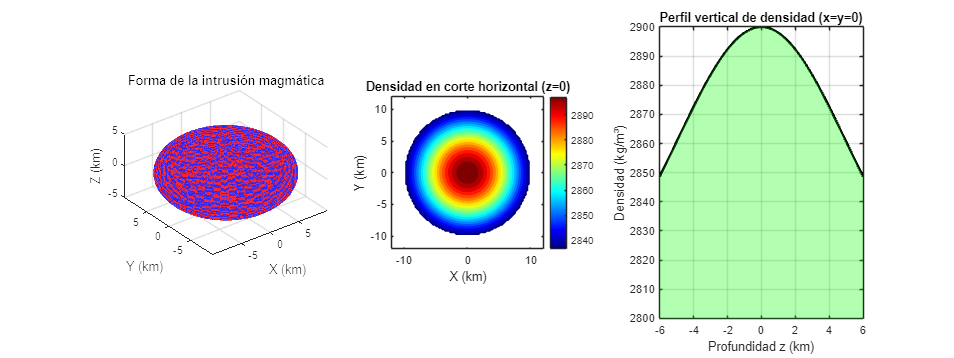


    % Visualización
    figure('Position', [100, 100, 1600, 600]);

    % 1. Gráfica 3D de la forma de la intrusión
    subplot(1, 3, 1);

    % Crear malla para la superficie
    u = linspace(0, 2 * pi, 50);
    v = linspace(0, pi, 50);
    [U, V] = meshgrid(u, v);
    x = 10 * cos(U) .* sin(V);
    y = 10 * sin(U) .* sin(V);
    z = 5 * cos(V);

    % Graficar superficie
    surf(x, y, z, 'FaceColor', 'red', 'FaceAlpha', 0.6, 'EdgeColor', 'none');
    hold on;
    surf(x, y, -z, 'FaceColor', 'blue', 'FaceAlpha', 0.6, 'EdgeColor', 'none');
    hold off;
    title('Forma de la intrusión magmática');
    xlabel('X (km)');
    ylabel('Y (km)');
    zlabel('Z (km)');
    axis equal;

    % 2. Mapa de densidad en corte horizontal (z=0)
    subplot(1, 3, 2);
    x_vals = linspace(-12, 12, 100);
    y_vals = linspace(-12, 12, 100);
    [X, Y] = meshgrid(x_vals, y_vals);
    Z = zeros(size(X));
    D = densidad_intrusion(X, Y, Z);

    % Aplicar máscara para mostrar solo dentro del elipsoide
    mask = (X.^2 + Y.^2) > 100;
    D(mask) = NaN;

    contourf(X, Y, D, 20, 'LineColor', 'none');
    colormap jet;
    colorbar;
    title('Densidad en corte horizontal (z=0)');
    xlabel('X (km)');
    ylabel('Y (km)');
    axis equal;

    % 3. Perfil vertical de densidad
    subplot(1, 3, 3);
    z_vals = linspace(-6, 6, 100);
    rho_vals = densidad_intrusion(0, 0, z_vals);
    plot(z_vals, rho_vals, 'k-', 'LineWidth', 2);
    hold on;
    fill([z_vals, fliplr(z_vals)], [2800 * ones(size(z_vals)), fliplr(rho_vals)], ...
         'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    hold off;
    title('Perfil vertical de densidad (x=y=0)');
    xlabel('Profundidad z (km)');
    ylabel('Densidad (kg/m³)');
    grid on;


    % Ajustar diseño
    set(gcf, 'Color', 'w');

### Ejercicio 1

Obten la masa total de la intrusion si la geometría de la intrusión es mas oblada de prolada. Usa la función $\frac{x^2}{25}+\frac{y^2}{25}+\frac{z^2}{100}\leq 1$.

## Ejemplo 2

Calcular el flujo total de energía solar a través de una región de la magnetopausa. El flujo se establece por la función 


$$F(x,y,z)=\frac{1.5+\text{sen}(2\theta)+0.2\text{cos}\phi}{r^2}\cdot 10^{-9}$$$


con unidades de $W/m^2$ y donde la transformación a coordenadas esféricas esta dada por $r=\sqrt{x^2+y^2+z^2}$, $\theta=\text{arccos}(z/r)$ y $\phi=\text{arctan(y/x)}$.

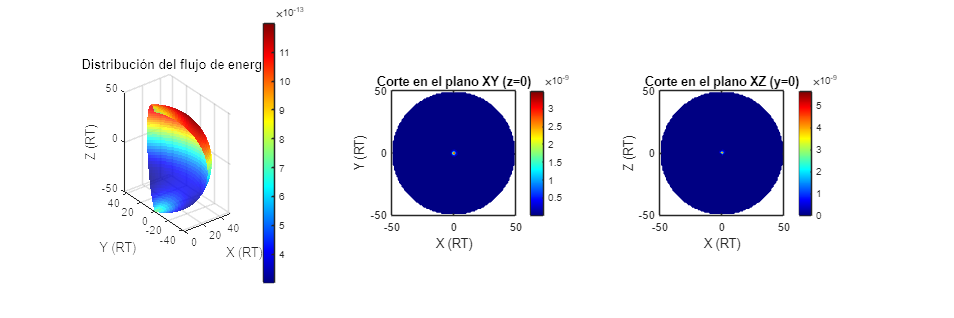

    % Figura para visualización
    figure('Position', [100, 100, 1800, 600]);

    % 1. Visualización 3D esférica
    subplot(1, 3, 1);

    % Crear esfera
    u = linspace(-pi/3, pi/3, 60);
    v = linspace(0, pi, 60);
    [U, V] = meshgrid(u, v);
    X = 50 * cos(U) .* sin(V);
    Y = 50 * sin(U) .* sin(V);
    Z = 50 * cos(V);

    % Calcular flujo
    F = flujo_energia(X, Y, Z);

    % Graficar superficie coloreada
    surf(X, Y, Z, F, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
    colormap('jet');
    colorbar;
    title('Distribución del flujo de energía');
    xlabel('X (RT)');
    ylabel('Y (RT)');
    zlabel('Z (RT)');
    axis equal;

    % 2. Mapa 2D en plano XY
    subplot(1, 3, 2);
    x = linspace(-50, 50, 100);
    y = linspace(-50, 50, 100);
    [X, Y] = meshgrid(x, y);
    Z = zeros(size(X));
    F_xy = flujo_energia(X, Y, Z);

    % Aplicar máscara para la región de integración
    mask = (X.^2 + Y.^2) > 50^2;
    F_xy(mask) = NaN;

    contourf(X, Y, F_xy, 20, 'LineColor', 'none');
    colormap('jet');
    colorbar;
    title('Corte en el plano XY (z=0)');
    xlabel('X (RT)');
    ylabel('Y (RT)');
    axis equal;

    % 3. Mapa 2D en plano XZ
    subplot(1, 3, 3);
    x = linspace(-50, 50, 100);
    z = linspace(-50, 50, 100);
    [X, Z] = meshgrid(x, z);
    Y = zeros(size(X));
    F_xz = flujo_energia(X, Y, Z);

    % Aplicar máscara
    mask = (X.^2 + Z.^2) > 50^2;
    F_xz(mask) = NaN;

    contourf(X, Z, F_xz, 20, 'LineColor', 'none');
    colormap('jet');
    colorbar;
    title('Corte en el plano XZ (y=0)');
    xlabel('X (RT)');
    ylabel('Z (RT)');
    axis equal;


    % Ajustar diseño
    set(gcf, 'Color', 'w');




# FUNCIONES

function integral = simpson_3d(f, a, b, c, d, e, f_limits, n)
    % Integración triple usando la regla de Simpson compuesta
    %
    % Parámetros:
    %   f: función a integrar f(x, y, z)
    %   a, b: límites en x
    %   c, d: límites en y (pueden ser funciones de x o constantes)
    %   e, f_limits: límites en z (pueden ser funciones de x, y o constantes)
    %   n: número de intervalos (debe ser par)
    %
    % Retorna:
    %   Valor de la integral triple

    if mod(n, 2) ~= 0
        n = n + 1; % Asegurar que n es par
    end

    hx = (b - a) / n;
    integral = 0.0;

    for i = 0:n
        x = a + i * hx;
        % Peso de Simpson para x
        wx = (hx / 3) * (1 * (i == 0 || i == n) + 4 * mod(i, 2) * (i ~= 0 && i ~= n) + 2 * (~mod(i, 2) && i ~= 0 && i ~= n));
        
        % Calcular límites en y
        if isa(c, 'function_handle')
            y_min = c(x);
        else
            y_min = c;
        end

        if isa(d, 'function_handle')
            y_max = d(x);
        else
            y_max = d;
        end
        
        hy = (y_max - y_min) / n;

        for j = 0:n
            y = y_min + j * hy;
            % Peso de Simpson para y
            wy = (hy / 3) * (1 * (j == 0 || j == n) + 4 * mod(j, 2) * (j ~= 0 && j ~= n) + 2 * (~mod(j, 2) && j ~= 0 && j ~= n));
            
            % Calcular límites en z
            if isa(e, 'function_handle')
                z_min = e(x, y);
            else
                z_min = e;
            end

            if isa(f_limits, 'function_handle')
                z_max = f_limits(x, y);
            else
                z_max = f_limits;
            end
            
            hz = (z_max - z_min) / n;

            for k = 0:n
                z = z_min + k * hz;
                % Peso de Simpson para z
                wz = (hz / 3) * (1 * (k == 0 || k == n) + 4 * mod(k, 2) * (k ~= 0 && k ~= n) + 2 * (~mod(k, 2) && k ~= 0 && k ~= n));
                
                % Sumar contribución a la integral
                integral = integral + wx * wy * wz * f(x, y, z);
            end
        end
    end
end



% Función de flujo de energía
% 
function flujo = flujo_energia(x, y, z)
    % Calcular r, theta y phi
    r = sqrt(x.^2 + y.^2 + z.^2);
    theta = zeros(size(r));
    nonzero_mask = r > 0;
    theta(nonzero_mask) = acos(z(nonzero_mask) ./ r(nonzero_mask));
    phi = atan2(y, x);

    % Calcular flujo
    flujo = zeros(size(r));
    flujo(nonzero_mask) = (1.5 + sin(2 * theta(nonzero_mask)) + 0.5 * cos(phi(nonzero_mask))) ./ r(nonzero_mask).^2;
    flujo = 1e-9 * flujo;
end